samplerate = 8000;
n=0:(1/samplerate):2;
x = cos(2*pi*((1/3)*1000*(n.^3)));
soundsc(x, 8000);

R1.a)

The Chirp function shows that it should increase it's frequency with time.

The sound created did indeed show a increase of frequency with time.

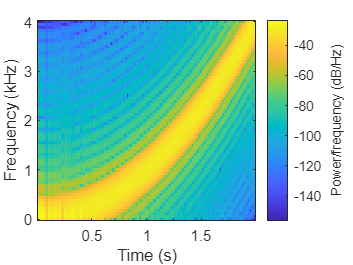

N=32; 
spectrogram(x, hann(N), 3*N/4, 4*N, 8000, "yaxis");

R2.a)

The Spectrogram shows graph of the function freq = (1/3)*1000*(t.^3). As expected we can see how the frequency increases with time. This is exaclty what we hear. As time increases, so does the frequency of the cherp

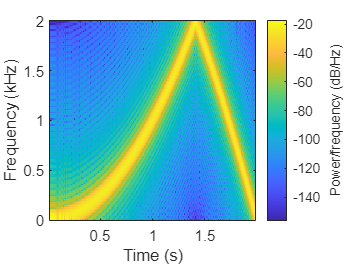

clear sound;

y_n = n(1:2:end);
y_sampleRate = 4000;
y = cos(2*pi*((1/3)*1000*((y_n).^3)));
soundsc(y, y_sampleRate);
y_N=64; 
spectrogram(y, hann(y_N), 3*y_N/4, 4*y_N, y_sampleRate, "yaxis");

R3.a)

The sampling frequency of y(n) is half of the sampling frequency of x(n) (4000 samples/s), as y(n) is only getting the odd n of x(n), meaning we have half of the samples of x(n). Therefore since we have half the samples/s the sampling rate will also be halfed.7

R3.b) 

I hear the frequency increasing with time, but but then theres a big drop around the 1.3 second mark. This is in accordence with the spectrogram of the signal.

R3.c)

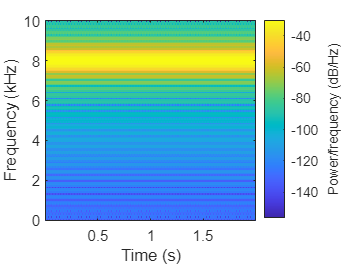

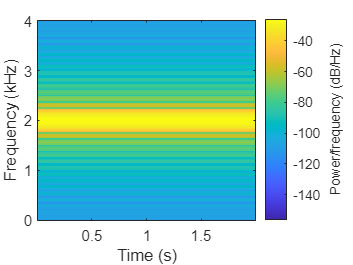

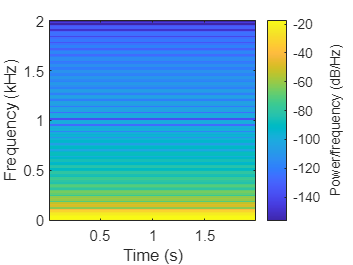

clear sound;

sample_Freq = [20000,8000,4000];
f= [8000,6000,4000];
z_N = 64;
for i =1:3
    t=0:(1/sample_Freq(i)):2;
    z=cos(2*pi*f(i)*t);
    figure();
    spectrogram(z, hann(z_N), 3*z_N/4, 4*z_N, sample_Freq(i), "yaxis");
end

To demonstrate what happened in with y(n), we chose the frequencies 8000Hz (f1), 6000Hz (f2) and 4000Hz (f3). 

We can see on the spectrogram that if we are lower then half of the sample frequency (f1), we can recreate the signal without any loss. This is what happens in y(n) until about the 1.3s mark.

On the spectrogram of the signal with a frequency greater then half of the sample frequency (f2), we can observe that the recreated signal has suffered allising and therefore is the difrence between the sample frequency and the signal frequency. This is what happens in y(n) between 1.3s and right before 2s.

On the spectrogram of the signal with a frequency equal to the sample frequency (f3), we can observe that the recreated signal also suffers allising. In this case the difrence between the sampling frequency and the signals frequency is 0, and therefore the resaulting signal is a constant. This is what happens in y(n) at the end of the spectrogram.

%number of seconds of the audio we want to listen
secLen = 15;
[Audio_X, Fs] = audioread("C:\Users\Gil Beirao\Desktop\Gils stuff\Universidade\2 - PDS\Lab1\romanza.wav");
soundsc(Audio_X(1:Fs*secLen), Fs);
Audio_N=64; 
spectrogram(Audio_X(1:Fs*secLen), hann(Audio_N), 3*Audio_N/4, 4*Audio_N, Fs, "yaxis");

R4.a)

To get 15 seconds of the audio we need to get (sample_freq * 15s) samples.

clear sound;    

Sampling_freq_ratio = 1/5;
Sampling_freq_Alising = Fs*Sampling_freq_ratio;

Audio_X_Alising = Audio_X(1:(1/Sampling_freq_ratio):Fs*secLen);

soundsc(Audio_X_Alising, Fs*Sampling_freq_ratio);
Audio_N=64; 
spectrogram(Audio_X_Alising, hann(Audio_N), 3*Audio_N/4, 4*Audio_N, Fs*Sampling_freq_ratio, "yaxis");

R5.a)

The lower frequencies of the violin are still audiable, but the higher frequencies sound like the wrong frequency. In general the music sounds like a lower quality of the original.

This is due to alising and can be clearly observed on the spectogram.

clear sound;

Sampling_freq_ratio = 1/5;
Sampling_freq_Alising = Fs*Sampling_freq_ratio;

xf = filter(fir1(100, 0.2), 1, Audio_X);

Audio_X_Anti_Alising = xf(1:(1/Sampling_freq_ratio):Fs*secLen);

soundsc(Audio_X_Anti_Alising, Fs*Sampling_freq_ratio);
Audio_N=64; 
spectrogram(Audio_X_Anti_Alising, hann(Audio_N), 3*Audio_N/4, 4*Audio_N, Fs*Sampling_freq_ratio, "yaxis");

R6.a)

The Lower frequencies are audiable and recognizable, but we can no longer hear the higher frequencies. In general the music still sounds like a lower quality of the original, but we can no longer hear interference in lower frequencies, like we did in R5.a).